clear all;

T = 1;
g0 = 2.8;
g1 = 0;


G_g = [0, 1; -1, 2];
init_g1 = g1*T + g0;
init_g2 = g0;
H_g = [1, 0];
G1 = -1;
G2 = 2;

%====================================
k1 = 3.26;
a01 = 1;
T1 = 9.5;
xi = 0.36;
k2 = 1;
a02 = 1;
T2 = 0;

a0 = (a01*a02) / (T1^2);
a1 = (2*xi) / T1;

b0 = k1*k2/(T1^2);

Ac = [0, 1; -a0, -a1];
Bc = [0; 1];
%C = [b0, 0];
C = [1, 0];

A = 0;
k = 100;
for i = 0:k
    A = A + (Ac^i * T^i) / factorial(i);
end
B = 0;
for i = 1:k
    B = B + ((Ac^(i - 1) * T^i) / factorial(i));
end

A;
B = B * Bc

B =     0.4872
    0.9613



Gg = G_g;
B_eta = [1; 0];
%B_eta = [1];
U = [B_eta, Gg*B_eta];
rank(U)

ans = 2


over_A = [G_g, -B_eta * C; zeros(2,2), A]

over_A =          0    1.0000   -1.0000         0
   -1.0000    2.0000         0         0
         0         0    0.9946    0.9613
         0         0   -0.0107    0.9217


%over_A = [-1, -B_eta*C; zeros(2,1), A]
over_B = [0; 0; B];

B_1 = [B_eta; 0; 0];

%U = [over_B, over_A*over_B, over_A^2*over_B];
%rank(U);

Gs = [0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1; 0, 0, 0, 0];
Hs = [1, 0, 0, 0];

P = sylvester(over_A, -Gs, over_B*Hs)

P =    -1.0248   -4.7067  -12.2505  -24.9115
   -0.5124   -2.6096   -7.4301  -16.1708
   -0.5124   -1.5848   -2.7233   -3.9202
    1.0370    1.1067    1.1692    1.2231


K = Hs * pinv(P)

K =    -3.6311    4.6704    4.3864    1.8512


d = det(P);
new_1 = over_A - over_B * K;
e = eig(new_1)

e = 1.0e-03 *

   0.1363 + 0.1363i
   0.1363 - 0.1363i
  -0.1363 + 0.1362i
  -0.1363 - 0.1362i



over_F = over_A - over_B * K

over_F =          0    1.0000   -1.0000         0
   -1.0000    2.0000         0         0
    1.7689   -2.2752   -1.1423    0.0595
    3.4905   -4.4895   -4.2272   -0.8577



B_g = B_1 + K(3).*over_B

B_g =     1.0000
         0
    2.1369
    4.2165


%B_g = over_B + K(3)*B_1
%C_y = [0,C, 0];
C_y = [0, 0, 1, 0]

C_y =      0     0     1     0


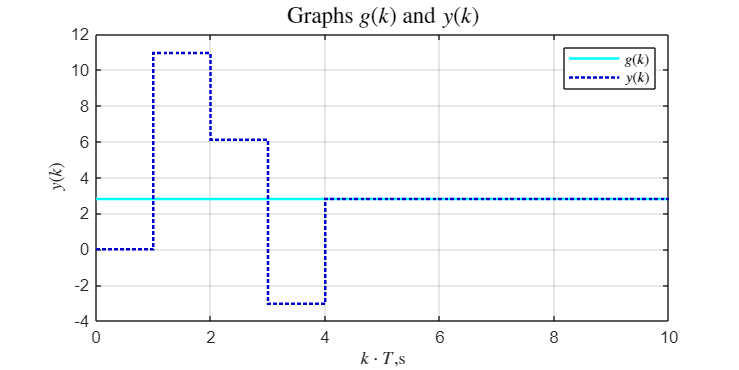



%====================================

set_param('task_2_schem/g', 'VariableName', 'g');
set_param('task_2_schem/e', 'VariableName', 'e');
set_param('task_2_schem/y', 'VariableName', 'y');

out = sim('task_2_schem');
t_time = out.g.Time;
g_data = out.g.Data;
e_data = out.e.Data;
y_data = out.y.Data;


% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);

stairs(t_time, g_data, '-', 'LineWidth', 1.5, 'Color', a_color);
hold on;
stairs(t_time, y_data, ':', 'LineWidth', 1.5, 'Color', d_color);

grid on;

title('Graphs $g(k)$ and $y(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$g(k)$','$y(k)$','Interpreter', 'latex')
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '2_gy.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

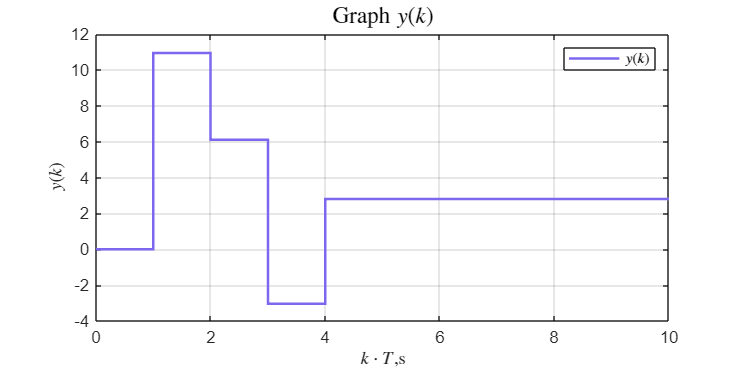


figure('Position', [100 100 800 400]);
stairs(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graph $y(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$y(k)$','Interpreter', 'latex')
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '2_y.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

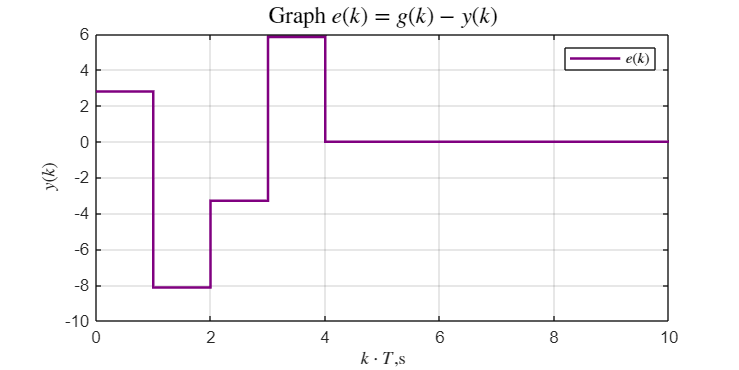



figure('Position', [100 100 800 400]);
stairs(t_time, e_data, '-', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $e(k) = g(k) - y(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$e(k)$','Interpreter', 'latex')
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '2_e.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);